# Baseline correction

Use the Matlab code below to download and plot the measurement data ([ZiheGao_MZI2_271_Scan1.mat](https://s3.amazonaws.com/edx-course-phot1x-chrostowski/Phot1x/ZiheGao_MZI2_271_Scan1.mat)). 

Choose the polynomial order (POLY_ORDER, or the value the polyfit function) to a value such at the polynomial follows the envelope of the MZI + Grating Couplers spectrum. Namely, the resulting polynomial should approximate the grating coupler insertion loss, and the flattened spectrum should look like the ideal MZI spectrum with the peaks at approximately 0 dB.

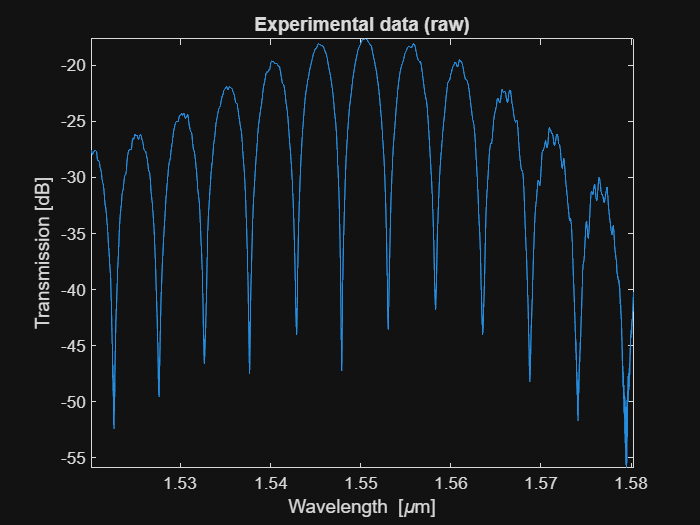

% Enter the order of the polynomial for the curve fitting:
POLY_ORDER = 1;

% Enter the Dropbox URL here.  Make sure it has a =1 at the end:
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
PORT=1; % Which Fibre array port is the output connected to?

a=websave('a.mat',url); % get data from Dropbox
load('a.mat');

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

% Plot the raw data:
figure;
plot (lambda*1e6, amplitude);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (raw)');

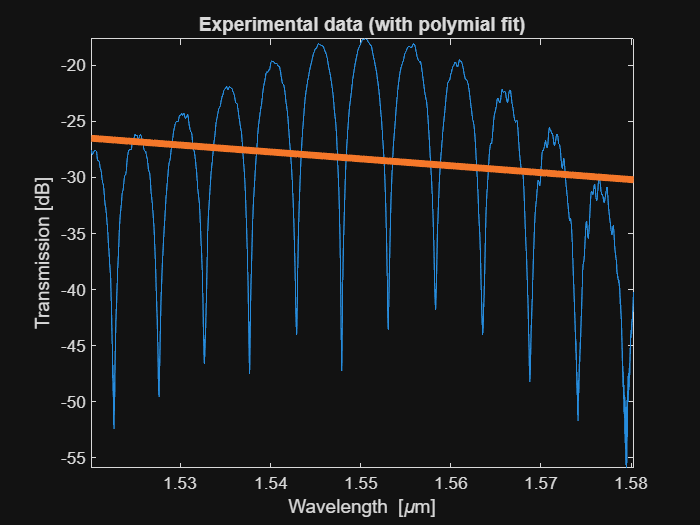


% Curve fit data to a polynomial for baseline correction
p=polyfit((lambda-mean(lambda))*1e6, amplitude, POLY_ORDER);
amplitude_baseline=polyval(p,(lambda-mean(lambda))*1e6); 
figure;
plot (lambda*1e6, amplitude); hold all;
plot (lambda*1e6, amplitude_baseline, 'LineWidth',4);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (with polymial fit)');

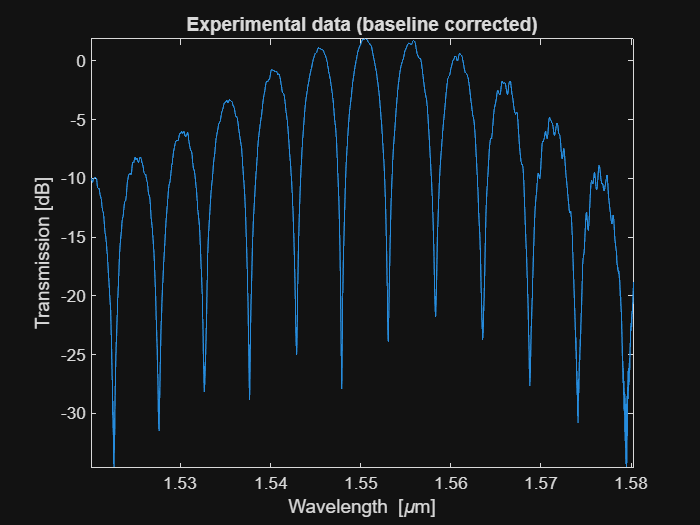


% Perform baseline correction to flatten the spectrum
% Use the curve polynomial, and subtract from original data
amplitude_corrected = amplitude - amplitude_baseline;
amplitude_corrected = amplitude_corrected + max(amplitude_baseline) - max(amplitude);
figure;
plot (lambda*1e6, amplitude_corrected);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (baseline corrected)');